# **Analisi di un  file audio**

In questo script viene analizzato un segnale musicale con frequenza di camponamento `Fs =8192Hz` in cui è presente un rumore stazionario. Si analizza il segnale in frequenza attraverso periodogramma e spettrogramma. Analizzando lo spettrogramma si individuerà il rumore, lo si eliminerà e si ricomporrà il segnale. Successivamente verranno rimostrati  periodogramma e spettrogramma,poi si scriverà il brano filtrato in un` file.wav col nome "Vicru_Noise_Removed.wav"`.

### Caricamento del File Audio e Grafico del Periodogramma in Frequenza e Decibel

In questa sezione viene caricato il file audio memorizzato sottoforma di file .mat.

song = load('vicru.mat');

Essendo un file audio campionato a 8 Bit bisogna considerare una frequenza di campionamento pari a 8192 Hz

Fc = 8192;
%Ricavo i valori della canzone memorizzati nelle Y del file caricato
ysong = song.y;

Proviamo ad ascoltare il suono del file audio attraverso il comando `sound` del Matlab

sound(ysong,Fc);

Ne mostriamo il periodogramma in frequenza e in decibel

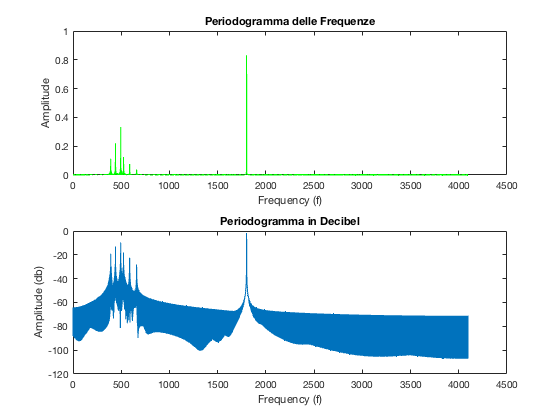

%Calcolo della DFT
F=fft(ysong);
n=length(ysong);
%Ampiezza per le frequenze simmetriche intorno alle frequenze di Nyquist
A=2*abs(F(1:floor(n/2)+1)/n);
freq=(0:n/2)*Fc/n;
subplot(2,1,1);
plot(freq,A,'g');
xlabel('Frequency (f)');
ylabel('Amplitude');
title('Periodogramma delle Frequenze');
Adb = mag2db(A); %Conversione ampiezza in decibel
subplot(2,1,2);
plot(freq,Adb);
xlabel('Frequency (f)');
ylabel('Amplitude (db)');
title('Periodogramma in Decibel');

Si può notare che intorno alle frequenze comprese tra 1500 e 2000, i periodogrammi mostrano un picco anomalo. Mostriamo dunque lo spettrogramma per identificare il rumore.

### Spettrogramma ed Eliminazione del Rumore

Mostriamo lo spettrogramma del fenomeno con l'ausilio della Finestra di Blackman e procediamo di conseguenza all'eliminazione del rumore rilevato.

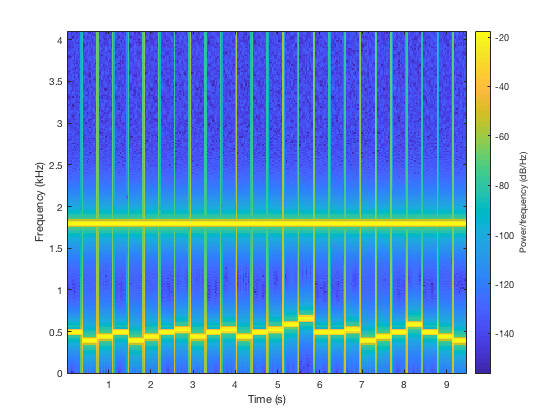

%Impostiamo la banda della finestra di Blackman
Nblack = 512;
%Mostriamo lo spettrogramma associato al fenomeno con il comando
%Spectrogram, la routine richiede l'overlap associato 
%che indica la frequenza di campionamento di base per la finestra
figure();
spectrogram(ysong,blackman(Nblack),floor(Nblack/2),Nblack,Fc,'yaxis');

Lo spettrogramma mostra un comportamento anomalo intorno ai 1.8 kHz di dB/kHz -90 dB corrispondenti. Questo ciò che mostrava il periodogramma precedente.

#### Rimozione Rumore

A questo punto rimuoviamo il rumore presente.

sound1=F;
%Annulliamo gli indici nella DFT con frequenze maggiori di 1500
indici=find(freq>=1500);
%Annulliamo anche i corrispettivi valori associati
sound1(1)=0;
indici(1)=[];
sound1(indici)=0;
%Eseguo lo stesso per Simmetria intorno alla frequenza di Nyquist
sound1(n+2-indici)=0;

### Ricostruzione del Segnale, Periodogramma e Spettrogramma

Procediamo alla ricostruzione del segnale e alla costruzione del periodogramma e dello spettrogramma associato.

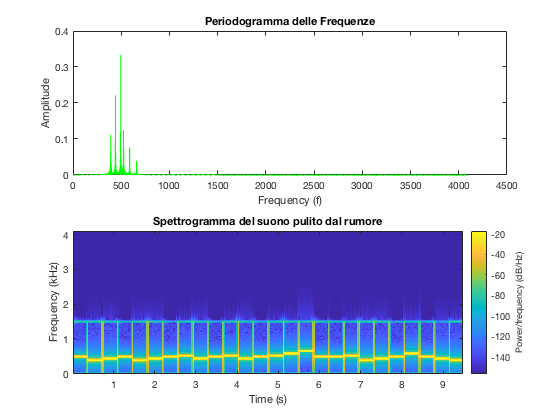

newsound=ifft(sound1);
n2=length(newsound);
F2=fft(newsound);
A2=2*abs(sound1(1:floor(n/2)+1)/n);
freq2=(0:n/2)*Fc/n2;
subplot(2,1,1);
plot(freq2,A2,'g');
xlabel('Frequency (f)');
ylabel('Amplitude');
title('Periodogramma delle Frequenze');
subplot(2,1,2);
spectrogram(newsound,blackman(Nblack),floor(Nblack/2),Nblack,Fc,'yaxis');
title('Spettrogramma del suono pulito dal rumore');

Si può notare che il rumore è stato completamente rimosso e dunque sia lo spettrogramma che il periodogramma mostrano alle frequenze maggiori di 1500 valori trascurabili.

### Salvataggio su File dell'Audio Ricostruito

Una volta mostrato il comportamento del segnale ricostruito, lo salviamo su di un file audio.

%Ascolto del suono ripulito
soundsc(real(newsound));

Da come si può ascoltare il suono viene completamente ripulito dal rumore, quest'ultimo era presente ad alte frequenze per questo motivo il suono risulta molto più cupo.

%Salviamo su di un file l'audio
audiowrite('Vicru_Noise_Removed.wav',newsound,Fc,'Comment','Suono vicru assente da Rumore');
%Mostriamo le informazioni sul file salvato
audioinfo('Vicru_Noise_Removed.wav')

ans = struct with fields:
             Filename: '/Users/raffaeleformisano/Desktop/Elaborato 7 Matlab/Vicru_Noise_Removed.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8192
         TotalSamples: 78000
             Duration: 9.5215
                Title: []
              Comment: 'Suono vicru assente da Rumore'
               Artist: []
        BitsPerSample: 16


### Riferimenti

- [*Docenti.unina.it D'alessio Alessandra*](https://www.docenti.unina.it/#!/professor/414c455353414e4452414427414c455353494f444c534c534e3534433630463833394e/login)

- [Trasformata di Fourier Discreta](https://it.wikipedia.org/wiki/Trasformata_discreta_di_Fourier)

- [Audio and Video in MATLAB](https://it.mathworks.com/help/matlab/audio-and-video.html?searchHighlight=audio&s_tid=doc_srchtitle)

### Autori

***Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936***